clf
%%% RBE 594 - Capstone Design Experience %%%
%%% Jason Munger %%%

% L1 = 5;
% L2 = 25.2;
% L3 = 17;
L1 = 0;
L2 = 640;
L3 = 960;
% L_tot = L1+L2+L3;
L_tot = 1550;
% [L2, L3] = getLinkLengths(L_tot-L1, 1,1.5)

x = 1000

x = 1000

y = 0;
z = -500;
% p = [x,y,z]
[theta1, theta2, theta3] =workspace_IK([x,y,z], L1, L2, L3)

theta1 = 0

theta2 = 32.3911

theta3 = -93.7889

% angles = [theta1, theta2, theta3]
% isreal(angles)

theta1 = deg2rad(linspace(-45,45,21));
theta2 = deg2rad(linspace(-38,102,21));
theta3 = deg2rad(linspace(-134,0,21));
leg = [];

for i = 1:length(theta1)
    for j = 1:length(theta2)
        for k = 1:length(theta3)
            i;
            j;
            k;
            % DH Parameters (a, alpha, d, theta:
            Leg_DH = [ L1,        pi/2,       0,         theta1(i);
                       L2,           0,       0,         theta2(j);
                       L3,           0,       0,         theta3(k)];
            
            A01 = DH_func(Leg_DH(1,1), Leg_DH(1,2), Leg_DH(1,3),Leg_DH(1,4));
            A12 = DH_func(Leg_DH(2,1), Leg_DH(2,2), Leg_DH(2,3),Leg_DH(2,4));
            A23 = DH_func(Leg_DH(3,1), Leg_DH(3,2), Leg_DH(3,3),Leg_DH(3,4));
            
            T00 = DH_func(0, 0, 0, 0);
            T01 = A01;
            T02 = T01*A12;
            T03 = T02*A23;
            leg = [leg; T01(1,4),T01(2,4),T01(3,4),T02(1,4),T02(2,4),T02(3,4),T03(1,4),T03(2,4),T03(3,4)];
%             scatter3(T01(1,4),T01(2,4),T01(3,4),"red")
%             hold on
%             scatter3(T02(1,4),T02(2,4),T02(3,4),"blue",">")
%             scatter3(T03(1,4),T03(2,4),T03(3,4),"green","x")
        end
    end
end
             Leg_DH = [ L1,        pi/2,       0,         deg2rad(0);
                       L2,           0,       0,         deg2rad(32.3912);
                       L3,           0,       0,         deg2rad(-93.7889)];
            
            A01 = DH_func(Leg_DH(1,1), Leg_DH(1,2), Leg_DH(1,3),Leg_DH(1,4));
            A12 = DH_func(Leg_DH(2,1), Leg_DH(2,2), Leg_DH(2,3),Leg_DH(2,4));
            A23 = DH_func(Leg_DH(3,1), Leg_DH(3,2), Leg_DH(3,3),Leg_DH(3,4));
            
            T00 = DH_func(0, 0, 0, 0);
            T01 = A01;
            T02 = T01*A12;
            T03 = T02*A23

T03 = 	1.0e+03 *

    0.0005    0.0009         0    1.0000
   -0.0000    0.0000   -0.0010   -0.0000
   -0.0009    0.0005    0.0000   -0.5000
         0         0         0    0.0010


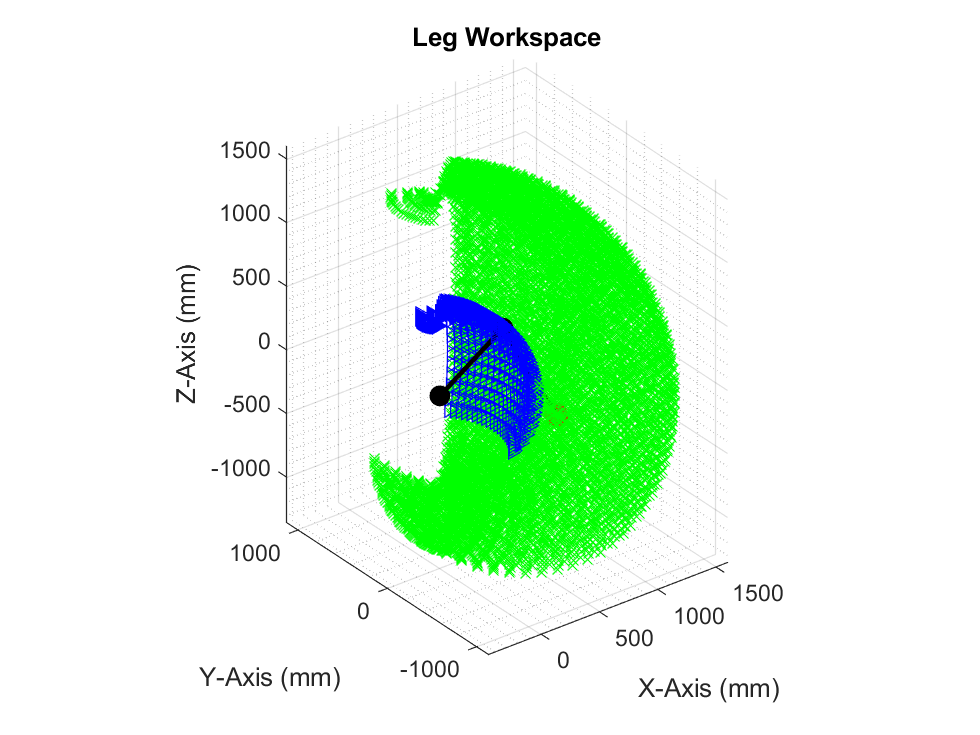

            
            scatter3(leg(:,1),leg(:,2),leg(:,3),"red")
            hold on
            scatter3(leg(:,4),leg(:,5),leg(:,6),"blue",">")
            scatter3(leg(:,7),leg(:,8),leg(:,9),"green","x")
            axis equal
%             view([0 90])
            plotRobot(T00, T01 ,T02, T03, 'Leg Workspace')

num_legs = 6;
beta = deg2rad(360/num_legs);
body_dia = 1250;
Rm = body_dia/2;
Rf = Rm + 1000;
hr = -400;


%Calculate joint positions
    s1 = [Rm*cos(2*beta), Rm*sin(2*beta), hr]'

s1 =  -312.5000
  541.2659
 -400.0000


    s2 = [Rm*cos(1*beta), Rm*sin(1*beta), hr]';
    s3 = [Rm*cos(3*beta), Rm*sin(3*beta), hr]';
    s4 = [Rm*cos(0*beta), Rm*sin(0*beta), hr]';
    s5 = [Rm*cos(4*beta), Rm*sin(4*beta), hr]';
    s6 = [Rm*cos(5*beta), Rm*sin(5*beta), hr]';

    
    s1f = [Rf*cos(2*beta), Rf*sin(2*beta), hr]'

s1f = 	1.0e+03 *

   -0.8125
    1.4073
   -0.4000


    s2f = [Rf*cos(1*beta), Rf*sin(1*beta), hr]';
    s3f = [Rf*cos(3*beta), Rf*sin(3*beta), hr]';
    s4f = [Rf*cos(0*beta), Rf*sin(0*beta), hr]';
    s5f = [Rf*cos(4*beta), Rf*sin(4*beta), hr]';
    s6f = [Rf*cos(5*beta), Rf*sin(5*beta), hr]';        
    
            
            
shift = [1250/2;0;0];
ang = 0:60:360;            
foot = leg(:,7:end)';
foot_shift = foot + shift

foot_shift = 	1.0e+03 *

    0.3094    0.3250    0.3496    0.3828    0.4242    0.4732    0.5292    0.5913    0.6587    0.7306    0.8059    0.8836    0.9627    1.0420    1.1204    1.1970    1.2706    1.3403    1.4051    1.4641    1.5165    0.3572    0.3822    0.4158    0.4575    0.5069    0.5631    0.6255    0.6932    0.7652    0.8407    0.9184    0.9975    1.0768    1.1552    1.2317    1.3052    1.3746    1.4392    1.4979    1.5500    1.5948    0.4090    0.4430    0.4851    0.5348    0.5913    0.6539    0.7218    0.7940
    0.3156    0.3000    0.2754    0.2422    0.2008    0.1518    0.0958    0.0337   -0.0337   -0.1056   -0.1809   -0.2586   -0.3377   -0.4170   -0.4954   -0.5720   -0.6456   -0.7153   -0.7801   -0.8391   -0.8915    0.2678    0.2428    0.2092    0.1675    0.1181    0.0619   -0.0005   -0.0682   -0.1402   -0.2157   -0.2934   -0.3725   -0.4518   -0.5302   -0.6067   -0.6802   -0.7496   -0.8142   -0.8729   -0.9250   -0.9698    0.2160    0.1820    0.1399    0.0902    0.0337   -

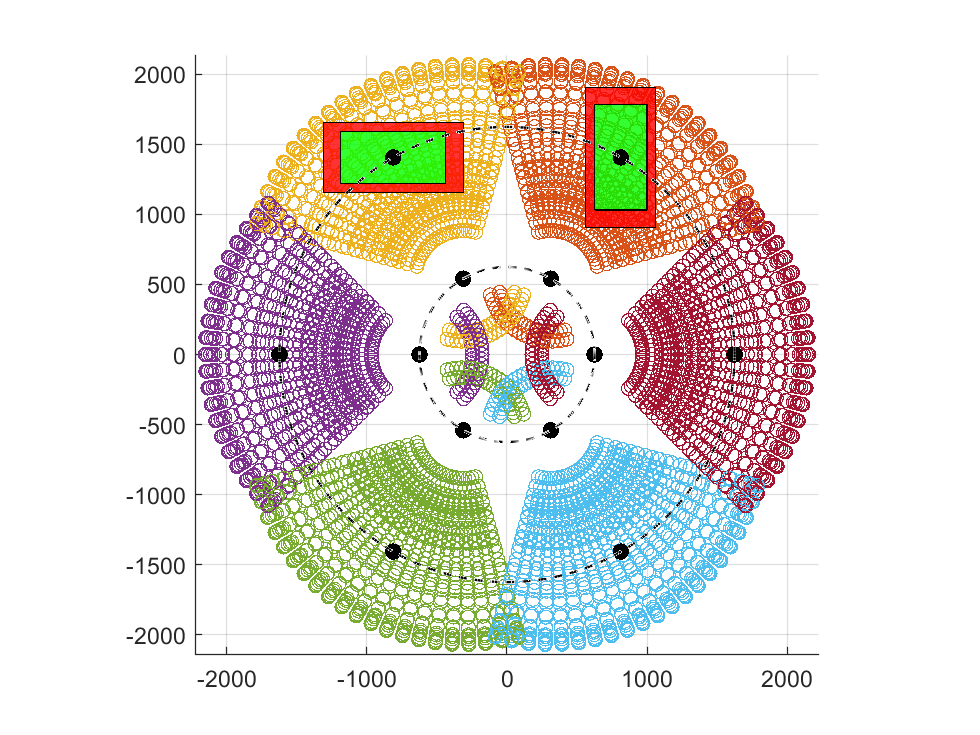

figure()
for i = 1:length(ang-1)
    foot_rot = Rotz(deg2rad(ang(i)))*foot_shift;

    scatter3(foot_rot(1,:),foot_rot(2,:),foot_rot(3,:))
    hold on
%     scatter3(foot_shift(1,:),foot_shift(2,:),foot_shift(3,:),"blue",">")

end
s = 1625;
h = -400;
s = [s1, s2, s3, s4, s5, s6];
scatter3(s(1,:),s(2,:),s(3,:),50,'filled',"MarkerFaceColor",'k')
sf = [s1f, s2f, s3f, s4f, s5f, s6f];
scatter3(sf(1,:),sf(2,:),sf(3,:),50,'filled',"MarkerFaceColor",'k')
w= 250;
l = 500;
w1= 0.75*w;
l1 = 375;
patch([s2f(1)+w s2f(1)-w s2f(1)-w s2f(1)+w], [s2f(2)+l s2f(2)+l s2f(2)-l s2f(2)-l], [h h h h], [s2f(2)+l s2f(2)+l s2f(2)-l s2f(2)-l],'FaceColor','red','FaceAlpha',.8)  
patch([s2f(1)+w1 s2f(1)-w1 s2f(1)-w1 s2f(1)+w1], [s2f(2)+l1 s2f(2)+l1 s2f(2)-l1 s2f(2)-l1], [h h h h], [s2f(2)+l1 s2f(2)+l1 s2f(2)-l1 s2f(2)-l1],'FaceColor','green','FaceAlpha',.8)   

patch([s1f(1)+l s1f(1)-l s1f(1)-l s1f(1)+l], [s1f(2)+w s1f(2)+w s1f(2)-w s1f(2)-w], [h h h h], [s1f(2)+w s1f(2)+w s1f(2)-w s1f(2)-w],'FaceColor','red','FaceAlpha',.8)  
patch([s1f(1)+l1 s1f(1)-l1 s1f(1)-l1 s1f(1)+l1], [s1f(2)+w1 s1f(2)+w1 s1f(2)-w1 s1f(2)-w1], [h h h h], [s1f(2)+w1 s1f(2)+w1 s1f(2)-w1 s1f(2)-w1],'FaceColor','green','FaceAlpha',.8)     
% viscircles([0,0], 250)
plotCircle(625,h,0,0,'k')
plotCircle(1000+625,h,0,0,'k')
axis equal
zlim([-600,-400])
view([0 90])

% figure()
% contour(foot_rot(1,:), foot_rot(2,:),foot_rot(3,:))
% find((foot_rot(3,:)<= -499) & (foot_rot(3,:)>= -501))
% foot_rot(:,210)

% 
% plotRobot(T00, T01 ,T02, T03, 'test plot')
% xlim([-(L1+L2+L3+250)/2,(L1+L2+L3+250)])
% ylim([-(L1+L2+L3+250),(L1+L2+L3+250)])
% zlim([-(L1+L2+L3+250),(L1+L2+L3+250)])

% 
% X = linspace(-50,L_tot,100);
% Y = linspace(-L_tot,L_tot,100);
% Z = linspace(-L_tot,L_tot,100);
% workspace = [];
% 
% for i = 1:length(X)
%     for j= 1:length(Y)
%         for k = 1:length(Z)
%             x = X(i);
%             y = Y(j);
%             z = Z(k);
%             [theta1, theta2, theta3] =workspace_IK([x,y,z], L1, L2, L3);
%             isvalid = isreal([theta1, theta2, theta3]);
%             if isvalid
%                 if (theta1 >=rad2deg(-pi/4)) && (theta1 <= rad2deg(pi/4))
%                     if (theta2 >=rad2deg(-pi/4)) && (theta2 <= rad2deg(pi/2))
%                         if (theta3 >=rad2deg(0)) && (theta3 <= rad2deg(3*pi/4))
%                             workspace = [workspace; [x,y,z,theta1, theta2, theta3]];
%                         end
%                     end
%                 end
%                 
%             end
%         end
%     end
% end

% 
% 
% scatter3(workspace(:,1),workspace(:,2),workspace(:,3))

function [L2, L3] = getLinkLengths(L, a, b)

    L2 = (a/(a+b))*L;
    L3 = (b/(a+b))*L;

end

function [theta1, theta2, theta3] = workspace_IK(p, L1, L2, L3)
    theta1 = rad2deg(atan2(p(2),p(1)));
    
    
    R = Rotz(deg2rad(theta1))';
    T = [R,-R'*[L1;0;0]; 0,0,0,1];
    p = [p';0];
    TT = T*p;
    
    l = sqrt((TT(1,end)-L1)^2+TT(3,end)^2);
    rho = atan((TT(3,end)/(TT(1,end)-L1)));
    theta2 = rad2deg(acos((L2^2+l^2-L3^2)/(2*L2*l))+rho);
    theta3 = rad2deg(-pi + acos((L2^2+L3^2-l^2)/(2*L2*L3)));
end


function H = DH_func(a, alpha, d,theta)

Rotation_Matrix_z_theta = [cos(theta) -sin(theta) 0 0; sin(theta) cos(theta) 0 0; 0 0 1 0; 0 0 0 1];

Translation_Matrix_z_d = [1 0 0 0; 0 1 0 0; 0 0 1 d; 0 0 0 1];

Translation_Matrix_x_a = [1 0 0 a; 0 1 0 0; 0 0 1 0; 0 0 0 1];

Rotation_Matrix_x_alpha = [1 0 0 0; 0 cos(alpha) -sin(alpha) 0; 0 sin(alpha) cos(alpha) 0; 0 0 0 1];

H = Rotation_Matrix_z_theta * Translation_Matrix_z_d * Translation_Matrix_x_a * Rotation_Matrix_x_alpha;

end

**Rotation Matrix about Z-Axis:**

function Rz = Rotz(theta)
%     theta = deg2rad(theta);
    Rz = [cos(theta) -sin(theta) 0;
          sin(theta)  cos(theta) 0
          0 0 1];
end


# Plotting Function (Stick Model):


function plotRobot(T00, T01 ,T02, T03, plot_title)

%Generate Links of Arm that Connect Joints (Plotting Purposes Only)
Link1 = [T00(1:3,4) T01(1:3,4)];
Link2 = [T01(1:3,4) T02(1:3,4)];
Link3 = [T02(1:3,4) T03(1:3,4)];



% Collect and store Coordinate Frame Origin X, Y, Z coordinates
Lx = [T00(1,4) T01(1,4) T02(1,4) T03(1,4)];
Ly = [T00(2,4) T01(2,4) T02(2,4) T03(2,4)];
Lz = [T00(3,4) T01(3,4) T02(3,4) T03(3,4)];


The robot links are plotted to the figure.

%Plot the links on a figure
plot3(Link1(1,:),Link1(2,:), Link1(3,:),'k', 'LineWidth', 2)
hold on
plot3(Link2(1,:),Link2(2,:), Link2(3,:),'k', 'LineWidth', 2)
plot3(Link3(1,:),Link3(2,:), Link3(3,:),'k', 'LineWidth', 2)


% Set up grid, axes, and labels
grid on
grid minor
xlabel('X-Axis (mm)')
ylabel('Y-Axis (mm)')
zlabel('Z-Axis (mm)')
title(plot_title)
axis equal

% axis([-250 250 -250 250 0 500]);
%
% %toggle view of plot by commenting/uncommenting out
% view([180,0])% Isoview


To assist in visualizing the coordinate frames as the joints move, the x, y, and z axes of each frame are plotted and update as the arm configuration updates along with the origins of each frame (black) and end effector frame (red).

%Plot Coordinate Frames

%Define length for each coordinate frame axis
axis_length = 50/1000;

%Plot o0x0y0z0 Coordinate Frame (World)
plot3([Lx(1), axis_length], [Ly(1) Ly(1)], [Lz(1), Lz(1)], 'Color', [1,0,1], 'LineWidth', 4)
plot3([Lx(1), Lx(1)], [Ly(1), axis_length], [Lz(1), Lz(1)], 'Color', [1,0,1], 'LineWidth', 4)
plot3([Lx(1), Lx(1)], [Ly(1) Ly(1)], [Lz(1), axis_length], 'Color', [1,0,1], 'LineWidth', 4)

%Plot o1x1y1z1 Coordinate Frame
plot3([Lx(2), (T01(1,1)*axis_length)+Lx(2)], [Ly(2), (T01(2,1)*axis_length)+Ly(2)], [Lz(2), (T01(3,1)*axis_length)+Lz(2)], 'Color', [1,0,0], 'LineWidth', 4)
plot3([Lx(2), (T01(1,2)*axis_length)+Lx(2)], [Ly(2), (T01(2,2)*axis_length)+Ly(2)], [Lz(2), (T01(3,2)*axis_length)+Lz(2)], 'Color', [0,1,0], 'LineWidth', 4)
plot3([Lx(2), (T01(1,3)*axis_length)+Lx(2)], [Ly(2), (T01(2,3)*axis_length)+Ly(2)], [Lz(2), (T01(3,3)*axis_length)+Lz(2)], 'Color', [0,0,1], 'LineWidth', 4)

%Plot o2x2y2z2 Coordinate Frame
plot3([Lx(3), (T02(1,1)*axis_length)+Lx(3)], [Ly(3), (T02(2,1)*axis_length)+Ly(3)], [Lz(3), (T02(3,1)*axis_length)+Lz(3)], 'Color', [1,0,0], 'LineWidth', 4)
plot3([Lx(3), (T02(1,2)*axis_length)+Lx(3)], [Ly(3), (T02(2,2)*axis_length)+Ly(3)], [Lz(3), (T02(3,2)*axis_length)+Lz(3)], 'Color', [0,1,0], 'LineWidth', 4)
plot3([Lx(3), (T02(1,3)*axis_length)+Lx(3)], [Ly(3), (T02(2,3)*axis_length)+Ly(3)], [Lz(3), (T02(3,3)*axis_length)+Lz(3)], 'Color', [0,0,1], 'LineWidth', 4)

%Plot o3x3y3z3 Coordinate Frame
plot3([Lx(4), (T03(1,1)*axis_length)+Lx(4)], [Ly(4), (T03(2,1)*axis_length)+Ly(4)], [Lz(4), (T03(3,1)*axis_length)+Lz(4)], 'Color', [1,0,0], 'LineWidth', 4)
plot3([Lx(4), (T03(1,2)*axis_length)+Lx(4)], [Ly(4), (T03(2,2)*axis_length)+Ly(4)], [Lz(4), (T03(3,2)*axis_length)+Lz(4)], 'Color', [0,1,0], 'LineWidth', 4)
plot3([Lx(4), (T03(1,3)*axis_length)+Lx(4)], [Ly(4), (T03(2,3)*axis_length)+Ly(4)], [Lz(4), (T03(3,3)*axis_length)+Lz(4)], 'Color', [0,0,1], 'LineWidth', 4)

% %Plot o4x4y4z4 Coordinate Frame
% plot3([Lx(5), (T04(1,1)*axis_length)+Lx(5)], [Ly(5), (T04(2,1)*axis_length)+Ly(5)], [Lz(5), (T04(3,1)*axis_length)+Lz(5)], 'Color', [1,0,0], 'LineWidth', 4)
% plot3([Lx(5), (T04(1,2)*axis_length)+Lx(5)], [Ly(5), (T04(2,2)*axis_length)+Ly(5)], [Lz(5), (T04(3,2)*axis_length)+Lz(5)], 'Color', [0,1,0], 'LineWidth', 4)
% plot3([Lx(5), (T04(1,3)*axis_length)+Lx(5)], [Ly(5), (T04(2,3)*axis_length)+Ly(5)], [Lz(5), (T04(3,3)*axis_length)+Lz(5)], 'Color', [0,0,1], 'LineWidth', 4)
% 
% %Plot o5x5y5z5 Coordinate Frame
% plot3([Lx(6), (T05(1,1)*axis_length)+Lx(6)], [Ly(6), (T05(2,1)*axis_length)+Ly(6)], [Lz(6), (T05(3,1)*axis_length)+Lz(6)], 'Color', [1,0,0], 'LineWidth', 4)
% plot3([Lx(6), (T05(1,2)*axis_length)+Lx(6)], [Ly(6), (T05(2,2)*axis_length)+Ly(6)], [Lz(6), (T05(3,2)*axis_length)+Lz(6)], 'Color', [0,1,0], 'LineWidth', 4)
% plot3([Lx(6), (T05(1,3)*axis_length)+Lx(6)], [Ly(6), (T05(2,3)*axis_length)+Ly(6)], [Lz(6), (T05(3,3)*axis_length)+Lz(6)], 'Color', [0,0,1], 'LineWidth', 4)
% 
% %Plot o6x6y6z6 Coordinate Frame
% plot3([Lx(7), (T06(1,1)*axis_length)+Lx(7)], [Ly(7), (T06(2,1)*axis_length)+Ly(7)], [Lz(7), (T06(3,1)*axis_length)+Lz(7)], 'Color', [1,0,0], 'LineWidth', 4)
% plot3([Lx(7), (T06(1,2)*axis_length)+Lx(7)], [Ly(7), (T06(2,2)*axis_length)+Ly(7)], [Lz(7), (T06(3,2)*axis_length)+Lz(7)], 'Color', [0,1,0], 'LineWidth', 4)
% plot3([Lx(7), (T06(1,3)*axis_length)+Lx(7)], [Ly(7), (T06(2,3)*axis_length)+Ly(7)], [Lz(7), (T06(3,3)*axis_length)+Lz(7)], 'Color', [0,0,1], 'LineWidth', 4)

%Plot origin points of each coordinate frame
scatter3(Lx(1:3), Ly(1:3), Lz(1:3), 80, 'o', 'filled', 'k');
%Plot origin point of end effector frame
scatter3(Lx(4), Ly(4), Lz(4), 100, 'o', 'filled', 'r');

end


function plotCircle(Rm,h,xc,yc,color)
    th = linspace(0,360,500);
    cir_x = Rm*cosd(th)+xc;
    cir_y = Rm*sind(th)+yc;
    cir_z = h*ones(length(cir_x),1)';
    plot3(cir_x,cir_y, cir_z,"Color",color,"LineWidth",1,'LineStyle','--')
end